clear all

figure;
tiledlayout(2, 1);

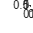

%%Align time of sleep stage data and Calculate average sleep time schedule
nexttile

folderName = 'PTSD';% Select 'PTSD' or 'Healthy'
[T,N]=load_patient_data_raw_withName(folderName);% Load all subject data.
% T: sleep stage data by numeric values
% one subject data in each cell
% one cell data > row: bin(30s), column: each night
% 0==Wake, 1==N1, 2==N2, 3==N3, 4==R, 5==NotScored
% N: subject IDs (column1) and their recording IDs (column2)
data = stage_replace(T, 0); % Separate Wake from others
% data: 0/1 sleep stage data (1==Wake 0==sleep stages)

A = get_record_start_time(folderName);% Check the time of the first epoch of the recording
[T_match, A] = align_time(A,N,data);% Align time across recordings within each subject
% T_match: time-aligned sleep stage data from the earliest sleep stage appearance to the latest sleep stage appearance
% A: sleep time schedule
% one subject data in each cell
% one cell data 
% > row: each night, 
%   column: [subject ID, recording ID, recording start time, recording start time*, 
%            time difference [m] from the earliest recording start time, sleep onset time*, sleep offset time*, recording end time*]
%           *minutes from 0:00


% Calculate average sleep time schedule for each subject
AverageTime = get_average_schedule(A);
% row: each subject
% column: [recording start time*, sleep onset time*, sleep offset time*, recording end time*, midpoint of the sleep*, recording duration [m], sleep duration [m]]
%          *minutes from 0:00

%%Calculate Sleep Regularity Index (SRI)
SRI = get_SRI(T_match);
% one subject data in each cell


%%Calculate the variability of sleep schedule (i.e. midpoint of the sleep) across subjects
ci = bootci(1000,@(x) std(x),AverageTime(:,5)); % Calculate the 95% confidence interval for the SD of midpoint of the sleep (Bias-corrected and acelerate bootstrap)
[std(AverageTime(:,5)),flip(ci')]% Print observed SD, upper ci, and lower ci.


%%Make a figure of average sleep schedule
hold on;
for i = 1:size(AverageTime,1)
    % box from recording start to end
    rectangle('Position', [AverageTime(i,1), i-0.35, AverageTime(i,6), 0.7], ...
              'EdgeColor', 'black', 'LineWidth', 1.5);

     
    % lines at sleep onset and end
    line([AverageTime(i,2), AverageTime(i,2)], [i-0.35, i+0.35], 'Color', 'black', 'LineWidth', 1.5);
    line([AverageTime(i,3), AverageTime(i,3)], [i-0.35, i+0.35], 'Color', 'black', 'LineWidth', 1.5);
    

    % recording start to sleep onset
    fill([AverageTime(i,1), AverageTime(i,2), AverageTime(i,2), AverageTime(i,1)], ...
         [i-0.35, i-0.35, i+0.35, i+0.35], [1 1 1], 'EdgeColor', 'none'); 

    % sleep onset to offset
    fill([AverageTime(i,2), AverageTime(i,3), AverageTime(i,3), AverageTime(i,2)], ...
         [i-0.35, i-0.35, i+0.35, i+0.35], [1.0000 0.3882 0.3882], 'EdgeColor', 'none'); % Healthy: 0.0745 0.6235 1.0000, PTSD: 1.0000 0.3882 0.3882

    % sleep offset to recoridng end
    fill([AverageTime(i,3), AverageTime(i,4), AverageTime(i,4), AverageTime(i,3)], ...
         [i-0.35, i-0.35, i+0.35, i+0.35], [0 0 0], 'EdgeColor', 'none'); 

    % lines at midpoint of the sleep
    line([AverageTime(i,5), AverageTime(i,5)], [i-0.35, i+0.35], 'Color', 'black', 'LineWidth', 1.5);

end

% x and y axis setting
xlabel('Time', 'FontSize',20,'FontWeight','bold');
ylabel('subject number', 'FontSize',20,'FontWeight','bold');

xlim([-400, 800]);
xticks([-360 -240 -120 0 120 240 360 480 600 720]);
xticklabels({'18:00', '20:00', '22:00', '0:00', '2:00', '4:00', '6:00', '8:00', '10:00', '12:00'});
yticks(0:5:30);

ax = gca;
ax.FontSize = 20;
ax.FontWeight = 'bold'; 

% Title
title('PTSD', 'FontSize', 35, 'FontWeight', 'bold'); % 'Healthy' or 'PTSD' 
